# Solution to *Delta-v for a Booster Rocket II *exercise

Use the rocket equation to calculate delta-v (total possible change of velocity) for a simple rocket, for a range of fuel masses. Assume that increasing fuel mass increases the height of the rocket, and therefore the mass of the rocket structure. For a fuel mass of m, the rocket equation for Δv becomes:


$$\Delta v = v_e \ln\left( 1+ \frac{m}{\alpha m + m_{fix}} \right)$$


where $$ is the effective exhaust velocity, $$ is the fixed mass of the rocket structure (such as the engine, which doesn’t depend on the fuel mass), and $$is a dimensionless parameter that depends on the geometry of the rocket and the densities of the fuel and structure. 

## 1. Previous exercise

ve = 2.6;       % exhaust velocity [km/s]
mfix = 6.1;     % fixed mass of rocket [tonnes (t)]
alpha = 0.15;   % ratio of mass of structure to mass of fuel

Create a vector of masses from 100 t to 1000 t.

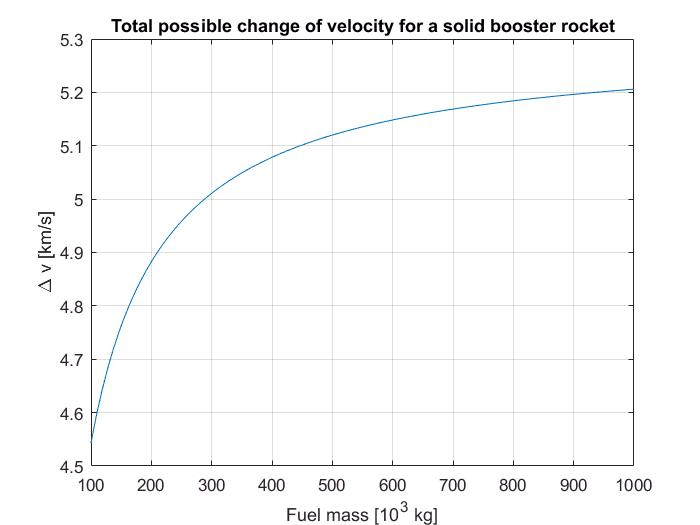

m = linspace(100,1000);

## 2. Create column vector `perc`

perc = (0.5:0.1:1.5)';

## 3. Multiply `alpha` by `perc` and plot

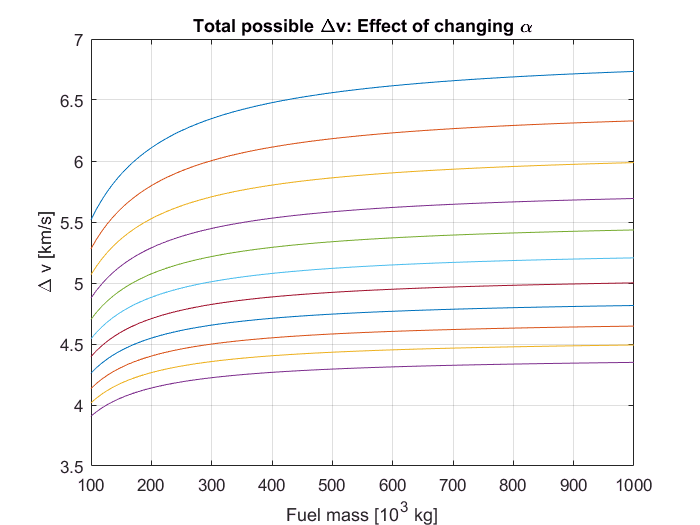

dv = ve*log(1 + m./(perc*alpha.*m+mfix));
plot(m,dv)
grid on
title('Total possible \Deltav: Effect of changing \alpha')
xlabel('Fuel mass [10^3 kg]')
ylabel('\Delta v [km/s]')

## 4. Multiply `mfix` by `perc` and plot

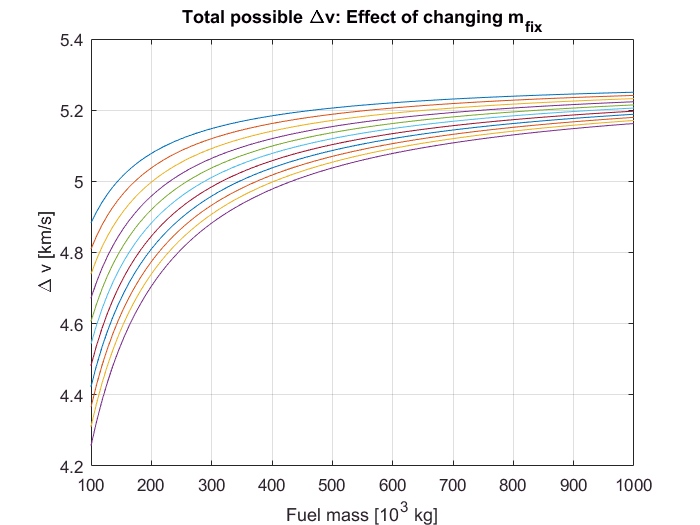

dv = ve*log(1 + m./(alpha*m+mfix*perc));
plot(m,dv)
grid on
title('Total possible \Deltav: Effect of changing m_{fix}')
xlabel('Fuel mass [10^3 kg]')
ylabel('\Delta v [km/s]')